%{
    Small script to visualize the values calculated by the 
    Program

%}

%Path of this script
this = matlab.desktop.editor.getActiveFilename;

%Path of the files
filePath = replaceBetween(this,"Anomaly_detection",length(this),"/test_gen/csv/");

%CSV files in the folder
files = dir(strcat(filePath,"*.csv"));

%Number of files
num_files = size(files);

disp("File disponibili:");

File disponibili:



%List the files
for y=1:num_files(1)
    disp(strcat(int2str(y),') ',files(y,:).('name'),newline));
end

1)Customer_Churn.csv
2)tripadvisor_review.csv
3)winequality_red.csv
4)winequality_white.csv



%Let the user choose the file
choice = -1;
while (isempty(choice) ...
        || ~isnumeric(choice) ...
        || ~isreal(choice) ...
        || ~isfinite(choice) ...
        || (choice ~= fix(choice)) ...
        || choice < 0 ...
        || choice > num_files(1) ...
        )

    choice = input("Scegli il file:");
end

%Open the file
tab = readtable(strcat(filePath,files(choice,:).('name')),VariableNamingRule="preserve");

disp(tab);

    User ID    Category 1    Category 2    Category 3    Category 4    Category 5    Category 6    Category 7    Category 8    Category 9    Category 10
    _______    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________

        1         0.93           1.8          2.29          0.62           0.8          2.42          3.19          2.79          1.82          2.42    
        2         1.02           2.2          2.66          0.64          1.42          3.18          3.21          2.63          1.86          2.32    
        3    


names = tab.Properties.VariableNames;

tab = tab{:,:};

rows = size(tab,1);
cols = size(tab,2);

%Let the user choose the window size
window = -1;
while (isempty(window) ...
        || ~isnumeric(window) ...
        || ~isreal(window) ...
        || ~isfinite(window) ...
        || (window ~= fix(window)) ...
        || window < 0 ...
        || window > rows ...
        )

    window = input("Scegli la dimensione della finestra:");
end

%Matrix containing the mean values
m = zeros(rows-window,cols);

%Matrix containing the covariance matrices
covar = zeros((rows-window)*cols,cols);

%Calculate the values
for tmp = 1:rows-window+1

    windows = tab(tmp:window+tmp-1,:);

    m(tmp,:) = mean(windows);

    covar(cols*(tmp-1)+1:cols*tmp,:) = cov(windows);

end

%Display the values
disp("Medie delle finestre:");

Medie delle finestre:


disp(m);

  250.5000    0.8870    1.3660    1.0198    0.5255    0.9471    1.8336    3.1809    2.8314    1.5573    2.8024
  251.5000    0.8870    1.3664    1.0191    0.5253    0.9476    1.8321    3.1809    2.8312    1.5570    2.8023
  252.5000    0.8904    1.3659    1.0166    0.5247    0.9468    1.8307    3.1809    2.8317    1.5556    2.8034
  253.5000    0.8898    1.3665    1.0204    0.5244    0.9480    1.8312    3.1809    2.8317    1.5558    2.8053
  254.5000    0.8902    1.3654    1.0208    0.5240    0.9485    1.8313    3.1809    2.8318    1.5570    2.8055
  255.5000    0.8911    1.3651    1.0192    0.5240    0.9469    1.8317    3.1809    2.8323    1.5577    2.8060
  256.5000    0.8941    1.3666    1.0182    0.5245    0.9470    1.8327    3.1809    2.8323    1.5574    2.8049
  257.5000    0.8941    1.3659    1.0203    0.5248    0.9464    1.8331    3.1809    2.8330    1.5591    2.8037
  258.5000    0.8940    1.3651    1.0234    0.5253    0.9507    1.8349    3.1809    2.8329    1.5583    2.8030
 


disp("Matrici delle covarianze per finestra:");

Matrici delle covarianze per finestra:


disp(covar);

   1.0e+04 *

    2.0875   -0.0001   -0.0001   -0.0004    0.0001    0.0002    0.0002   -0.0000    0.0001   -0.0003    0.0000
   -0.0001    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0004   -0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.00


disp("Andamento delle covarianze tra stream:");

Andamento delle covarianze tra stream:


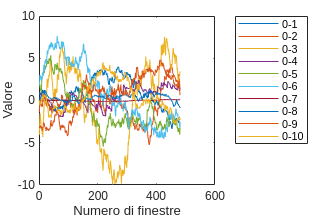

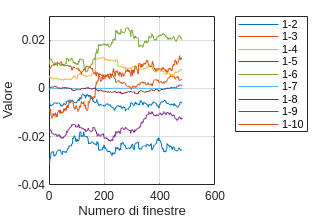

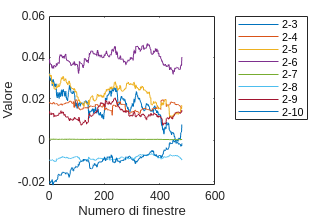

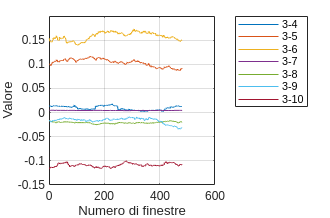

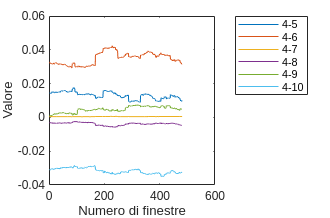

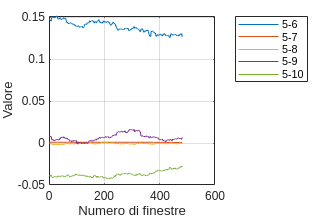

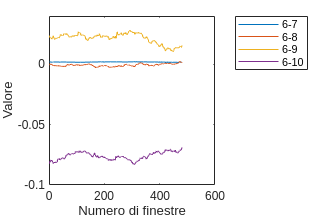

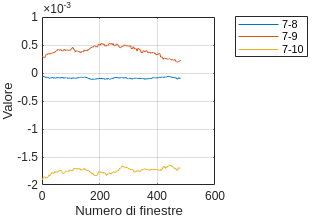


%Plot the covariances
for x = 1:cols-1
    tmp = 1;
    cov_names = strings(1,cols-x);
    figure;
    for y = 2:cols
        if(y>x)
            plot(covar(x:cols:end,y));
            grid;
            hold on
            cov_names(tmp) = strcat(int2str(x-1),"-",int2str(y-1));
            tmp = tmp + 1;
        end
    end
    set(gcf, 'unit', 'inches');
    figure_size =  get(gcf, 'position');
    h_legend = legend(cov_names);
    set(h_legend, 'location', 'northeastoutside');
    set(h_legend, 'unit', 'inches');
    legend_size = get(h_legend, 'position');
    figure_size(3) = figure_size(3) + legend_size(3);
    set(gcf, 'position', figure_size);
    xlabel("Numero di finestre");
    ylabel("Valore");
    hold off
end

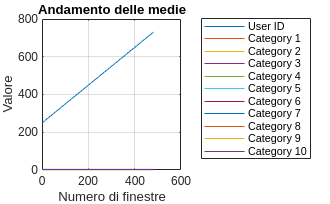


%Plot the mean
figure;
plot(m);
grid;
title("Andamento delle medie");
set(gcf, 'unit', 'inches');
figure_size =  get(gcf, 'position');
h_legend = legend(names);
set(h_legend, 'location', 'northeastoutside');
set(h_legend, 'unit', 'inches');
legend_size = get(h_legend, 'position');
figure_size(3) = figure_size(3) + legend_size(3);
set(gcf, 'position', figure_size);
xlabel("Numero di finestre");
ylabel("Valore");


clear;